# Lab - 07

format long e

## Question - 1

#### 4.2.19

N = [30,40,50,60];
M = [10,20,30,40];

for n = N
    for m = M
        A = randn(n,m);
        sing_vals = svd(A);
        min(sing_vals)
    end
end

ans =      2.744434522385057e+00


ans =      1.031945392774294e+00


ans =      2.143347576414241e-02


ans =      4.843046377195233e-01


ans =      3.109620626115417e+00


ans =      2.256686050821698e+00


ans =      7.742115483148664e-01


ans =      2.571001427137671e-02


ans =      3.949113573160750e+00


ans =      2.432278641121975e+00


ans =      1.836676095419292e+00


ans =      7.951805244491970e-01


ans =      4.551831992010047e+00


ans =      3.947246723747244e+00


ans =      2.581589388419664e+00


ans =      1.341163015317479e+00


It can be observed that almost everytime, all the matrices of different sizes initialised randomly have the lowest singular value as a large number far from unit round-off, which proves the claim of the exercise, i.e. a matrix chosen at random (nearly always) has full rank.

#### 4.2.20

A = randn(8,4);
A(:, [5,6]) = A(:, [1,2]) + A(:, [3,4]);
[Q,R] = qr(randn(6));
A = A*Q;

(a)

disp(A);

     1.554385889668464e+00     8.655157188001372e-02     1.081743711350996e+00    -2.046281850785391e+00     7.304566370733974e-01    -1.706788621597032e+00
    -6.482993188702155e-01     1.967359273284204e+00     2.193306668736834e+00     8.741821195305154e-01    -1.235665831292571e+00    -1.267705905120480e+00
    -5.158270957656420e-01    -5.243617294641963e-01    -1.963735820834747e+00     8.763041603406739e-01    -4.080781036173730e-01     1.768027131751429e+00
     3.636288470460114e-01    -6.622386192288355e-01    -5.340304413397230e-01    -1.848166286570154e+00     2.323363881966748e-01     2.226883928083656e-01
     2.673644701310822e+00    -1.089354579976605e+00    -1.343070511814106e+00     1.016805051277879e+00     2.132771725420617e+00    -6.403733033173168e-01
     1.728062321442715e+00    -1.202696276411069e+00    -2.241788421753824e+00    -9.509326481029680e-01     9.145045044981824e-01     6.577493342986154e-01
    -3.532446582838021e-01    -3.685531673551102e-01    -4

By looking at A, we can't say if it has a numerical rank 4.

(b)

sing_vals = svd(A)

sing_vals =      6.318177928327157e+00
     5.022650633311801e+00
     3.071023329875629e+00
     1.302040915899887e+00
     5.150444569863486e-16
     2.902053814353110e-16


threshold = 2 * 8 * eps * sing_vals(1)

threshold =      2.244667715106330e-14


It can be observed that 4 singular values are significantly large while remaining 2 are tiny, smaller than the threshold set by matlab to determine the numerical rank.

(c)

rank(A)

ans =      4


rank command gives the numerical rank of A as 4 as predicted above.

(d)

rank(A, 1e-17)

ans =      6


Changing the threshold to 1e-17 makes it smaller than the last 2 tiny singular values due to which the rank command with this modified threshold returns 6.

#### 4.2.21

A = gallery('kahan', 90,1.2,0);

(a)

max(diag(A))

ans =      1


min(diag(A))

ans =      1.903869390462388e-03


The largest main diagonal entry is 1 and the smallest is 0.0019... which is greater than 0.001.

(b)

sig = svd(A);
sing_vals = [sig(1); sig(89); sig(90)]

sing_vals =      8.789335328546843e+00
     2.384232536378107e-03
     3.960592002788876e-15


numerical_rank = rank(A)

numerical_rank =     89


threshold = 2 * 90 * eps * sig(1)

threshold =      3.512924083045447e-13


It can be seen than sig(1) is pretty large, sig(89) is still far from unit round-off, while sig(90) is a tiny value close to O(u) and is smaller than the threshold set by rank command in MATLAB, due to which the numerical rank returned by rank command is 89 as expected.

(c)

% slightly perturbed version of Kahan matrix
A = gallery('kahan', 90,1.2,25);

% steps of (b) for perturbed A
sig = svd(A);
sing_vals = [sig(1); sig(89); sig(90)]

sing_vals =      8.789335328546738e+00
     2.384232536386804e-03
     3.960619985337300e-15


numerical_rank = rank(A)

numerical_rank =     89


threshold_svd = 2 * 90 * eps * sig(1)

threshold_svd =      3.512924083045405e-13



% QR decomposition with column pivoting
[Q,R,E] = qr(A);
dif = norm(E - eye(90))

dif =      0


R(90,90)

ans =      1.903869390467939e-03


threshold_qr = eps * 90 * abs(R(1,1))

threshold_qr =      1.998401444326280e-14


Here, we can observe that for the slightly perturbed A, svd and rank command are still giving the numerical rank as 89 as the last singular value is O(u) and is smaller than the default threshold set by MATLAB which is calculated above.

While, the QR decomposition with column pivoting, results in a numerical rank of 90 since R(90,90) is a large value greater than the threshold determined for rank revealing QR decomposition, which means, QR decomposition with column pivoting failed to detect the numerical rank deficiency of A.

## Question - 2

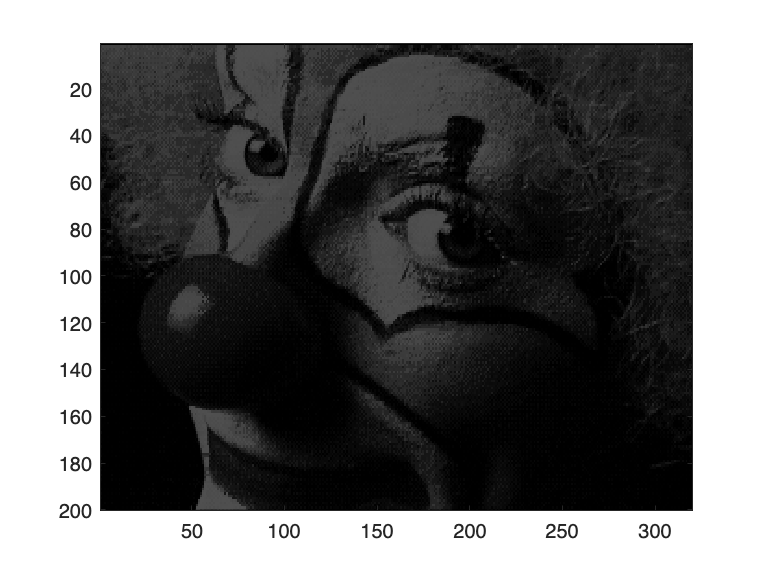

load clown.mat; 
[U, S, V] = svd(X); 
colormap('gray');

For k = 1


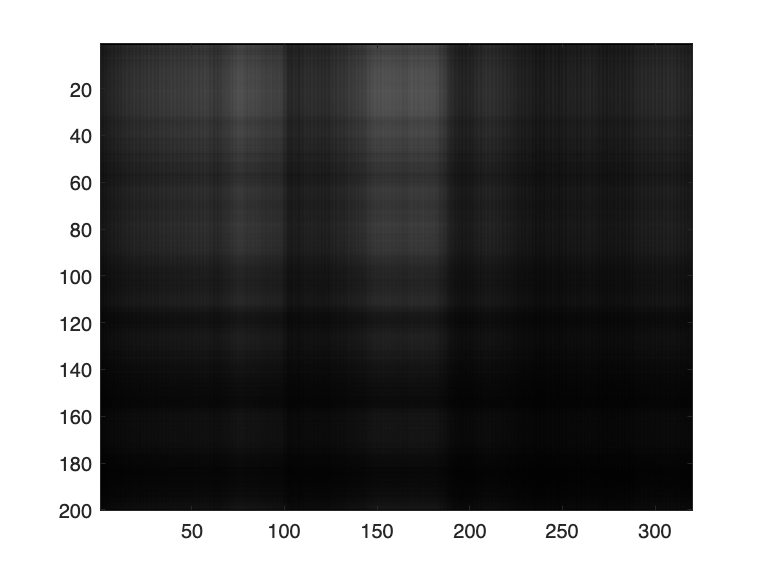

For k = 2


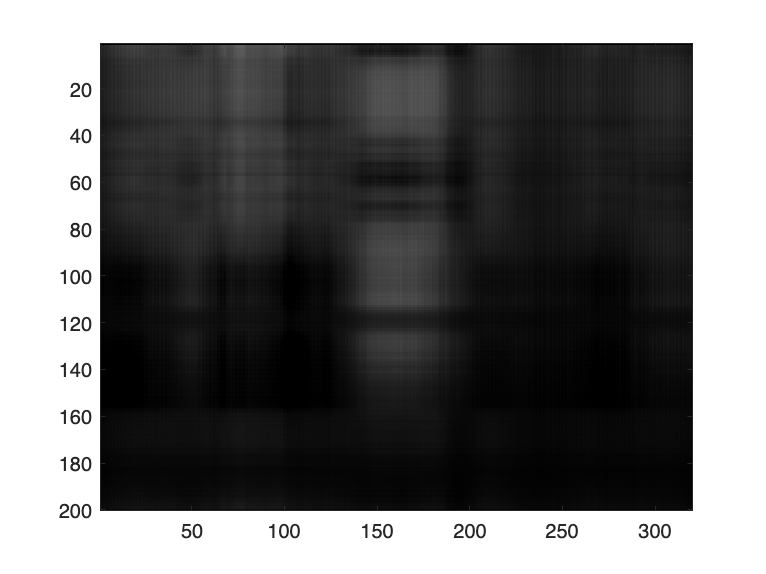

For k = 3


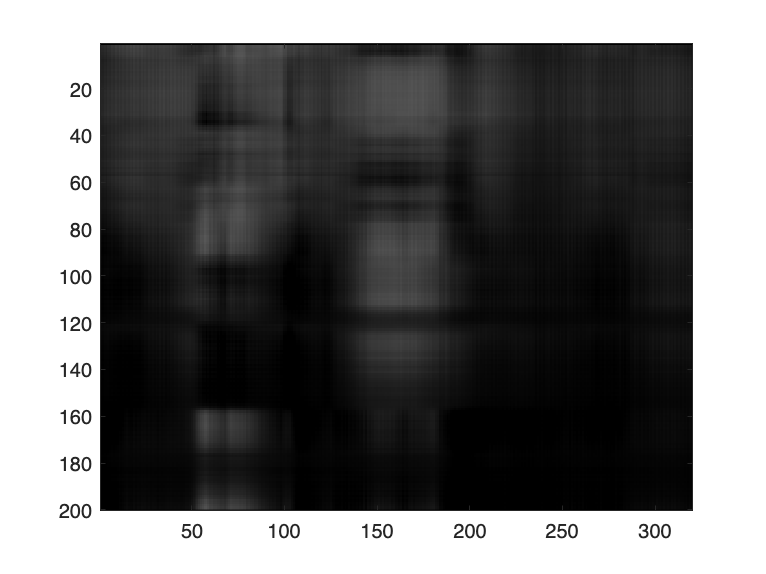

For k = 4


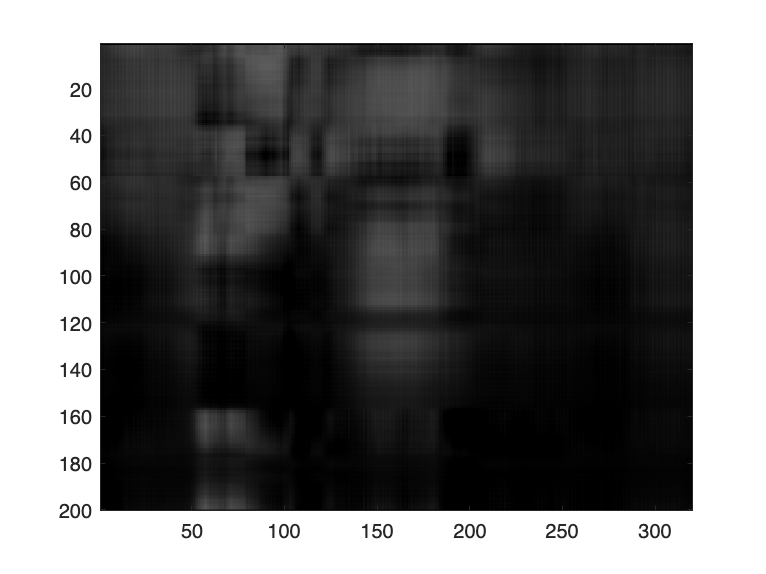

For k = 5


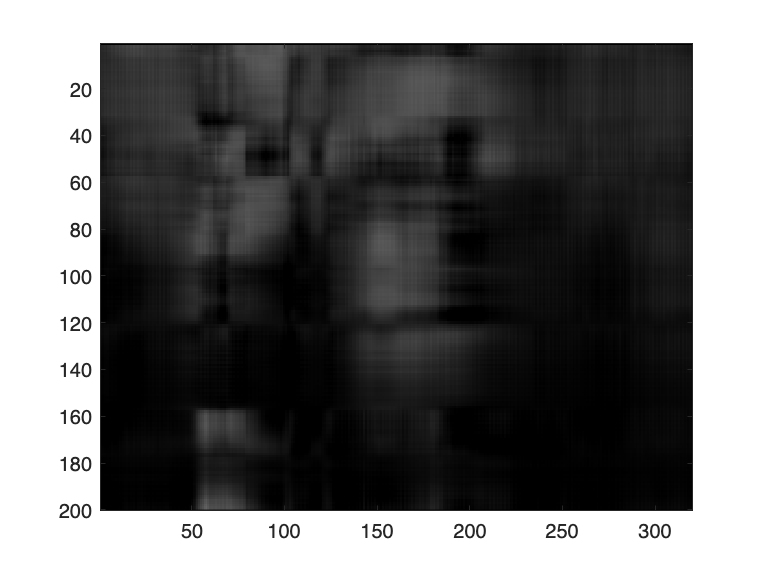

For k = 6


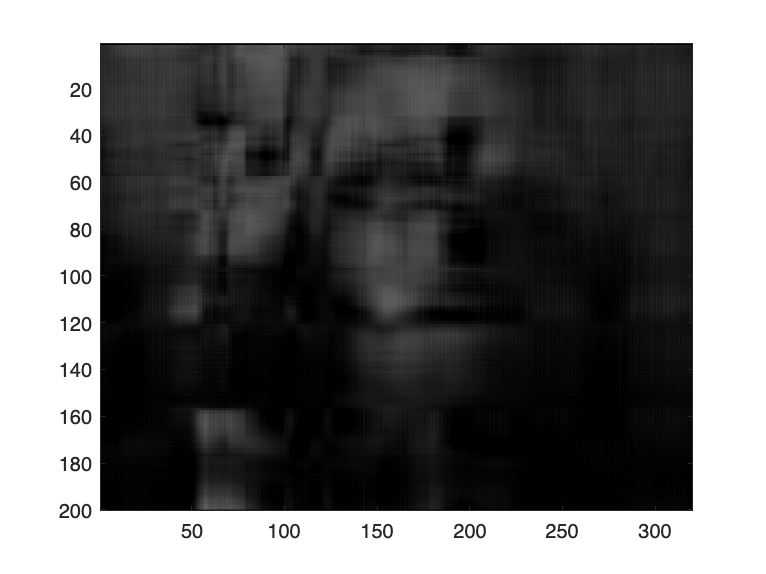

For k = 7


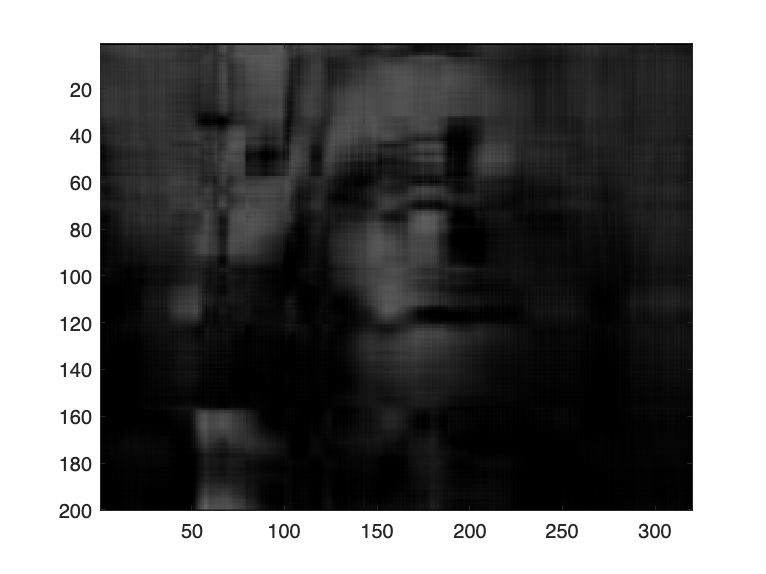

For k = 8


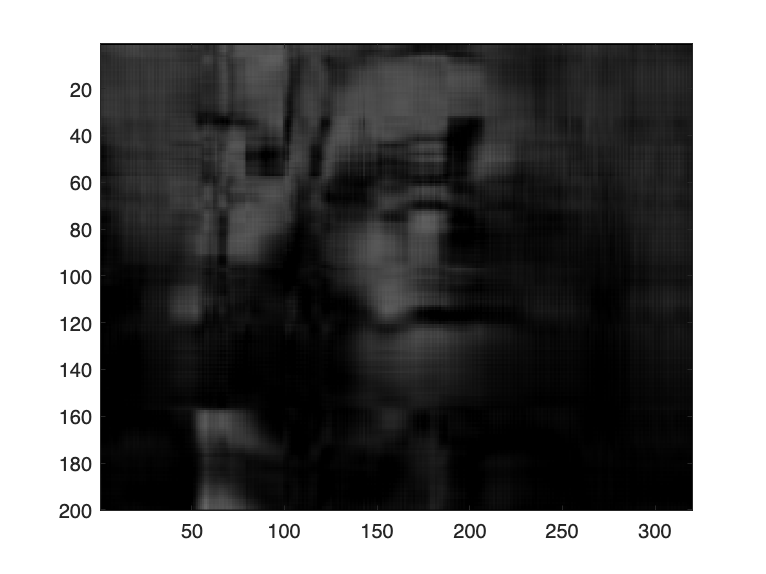

For k = 9


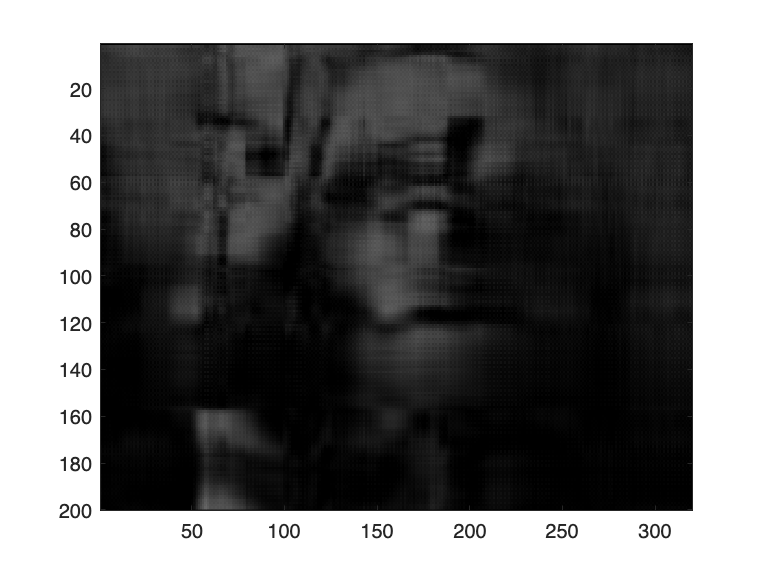

For k = 10


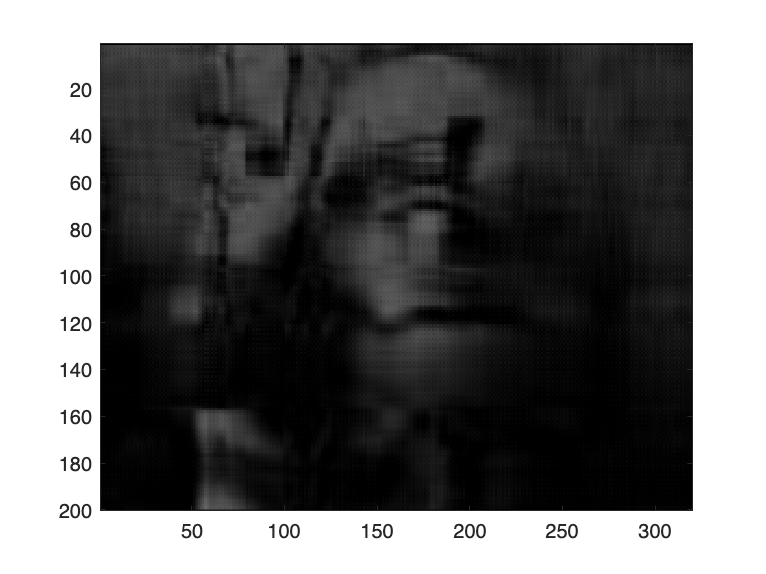

For k = 10


For k = 40


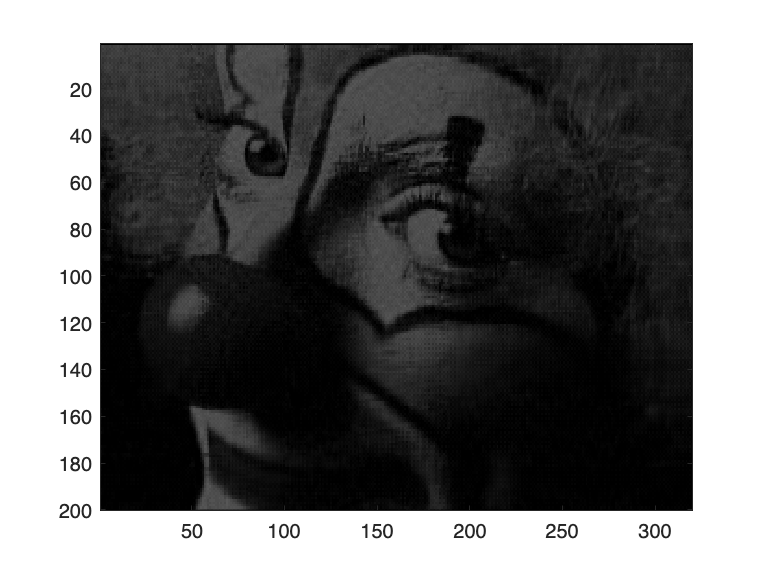

For k = 70


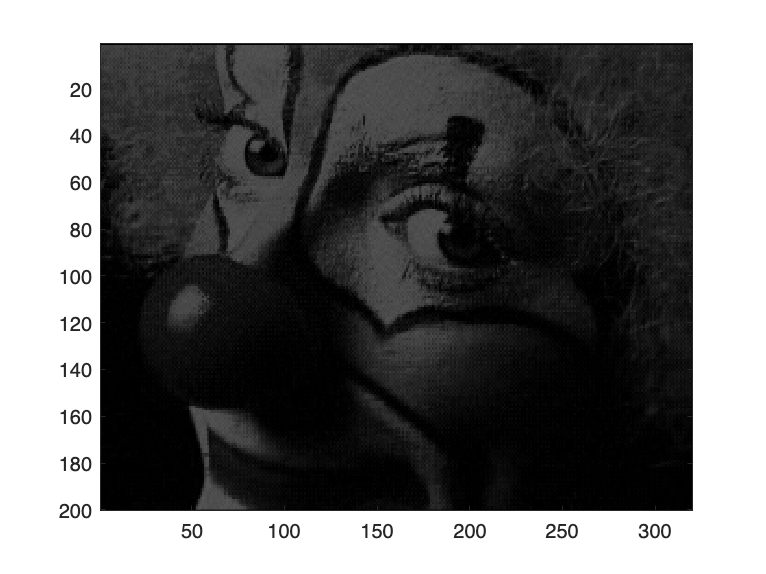

For k = 100


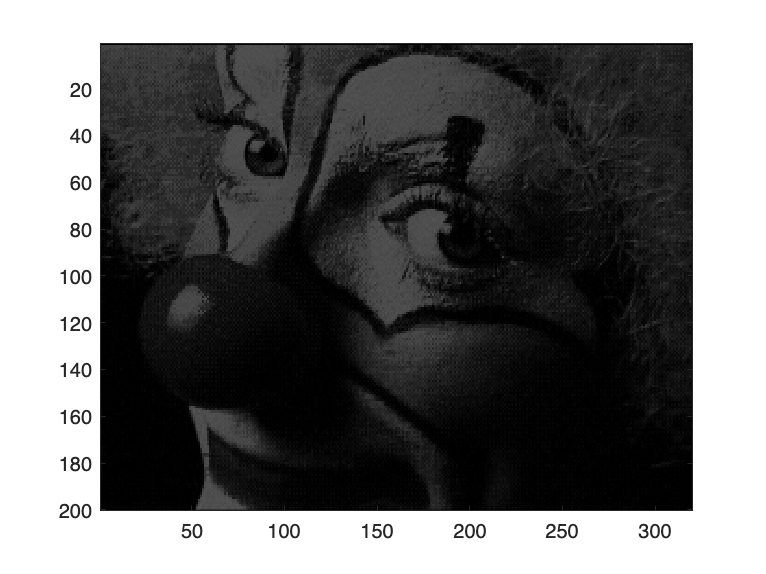

For k = 130


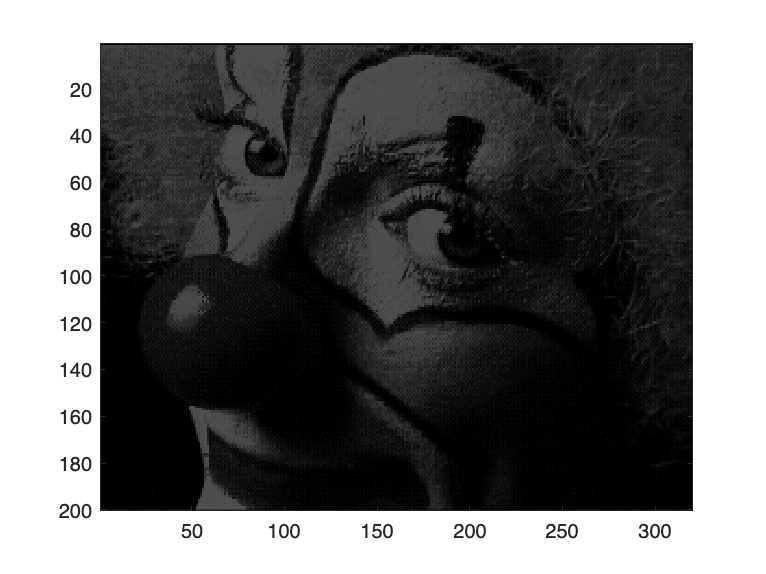

For k = 160


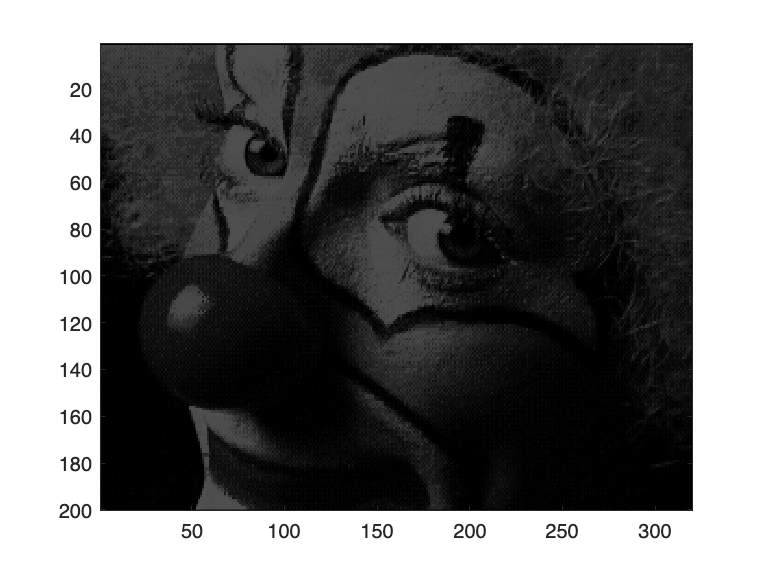

For k = 190


K = 1:10; K = [K, 10:30:200];
Comp_ratios = [];
Rel_Errors = [];
sig = diag(S);

for k = K
    fprintf('For k = %d\n',k);
    figure;
    image(U(:, 1:k)*S(1:k, 1:k)*V(:,1:k)')
    colormap('gray');
    hold off;

    Comp_ratios = [Comp_ratios, 540*k/6400];
    Rel_Errors = [Rel_Errors, sig(k+1)/sig(1)];
end


[K', Comp_ratios', Rel_Errors']

ans =      1.000000000000000e+00     8.437500000000001e-02     2.527571447003363e-01
     2.000000000000000e+00     1.687500000000000e-01     2.177853356348501e-01
     3.000000000000000e+00     2.531250000000000e-01     1.553997546650401e-01
     4.000000000000000e+00     3.375000000000000e-01     1.375199194689970e-01
     5.000000000000000e+00     4.218750000000000e-01     1.311622608718533e-01
     6.000000000000000e+00     5.062500000000000e-01     1.101745695346920e-01
     7.000000000000000e+00     5.906250000000000e-01     8.731866061752061e-02
     8.000000000000000e+00     6.750000000000000e-01     8.377060249911651e-02
     9.000000000000000e+00     7.593750000000000e-01     8.001275149042121e-02
     1.000000000000000e+01     8.437500000000000e-01     7.662053388634095e-02


It can be observed that the compression ratio is increasing with increase in k, while the relative error is decreasing. For a profitable compresstion, we want our compression ratio to be less than 1 and relative error should be as small as possible as per the requirement.